# Group 17: Assignment 2(Linear Growth Model) 

#### Members: 1. Riddhesh Tiwaskar(2017B4A30537P)                                                 

####                   2. Aman Gupta(2017B4A20835P)

Question: 

Consider a linear growth model with individual birth and death rate equal to (8.12n+2.43) per hour and (9.04n) per hour respectively. Initial value is five natives. 

- Simulate the system for 20 mins.

- Plot the distribution of linear growth model. 

- Estimate the time until extinction.

Setting Given values:

%Setting initial state(population)
ni=5

ni = 5

n=ni

n = 5

%Setting birth rate per min
bn=((8.12*n)+2.43)/60;
%Setting death rate per min
dn=(9.04*n)/60;
fprintf("Initial Birth and Death rate(per min) are %f, %f respectively \n",bn,dn)

Initial Birth and Death rate(per min) are 0.717167, 0.753333 respectively 


#### Simulating system for 20min:

disp("Now simulating given system for 20min.")

Now simulating given system for 20min.


para=bn+dn;
time_total=0;
holdtime=0;
Pm=[5];%Data variables for plotting
Tm=[0];%same
while (time_total+holdtime)<=20
    u=rand; %Random variable for hold time
    v=rand; %Random variable to simulate birth or death
    holdtime=(-1/para)*log(u);
    time_total=time_total+holdtime;
    fprintf("Time established in simulation is %f min",time_total)
    Pinc=bn/(bn+dn);
    Pdec=dn/(bn+dn);
    if v<Pinc
        n=n+1;%updating n
    else
        n=n-1;%updating n
    end
    fprintf("Current Population is %i inhabitant(s)",n)
    %Now updating changed birth/death rates
    bn=((8.12*n)+2.43)/60;
    dn=(9.04*n)/60;
    %Collecting Data points:
    Tm=[Tm,time_total];
    Pm=[Pm,n];
    if time_total+holdtime>=20
        fprintf("Final Population after 20min is %i inhabitant(s) \n \n \n",n)
    end
end

Time established in simulation is 0.252378 min

Current Population is 4 inhabitant(s)

Time established in simulation is 0.317222 min

Current Population is 5 inhabitant(s)

Time established in simulation is 0.983195 min

Current Population is 6 inhabitant(s)

Time established in simulation is 1.149208 min

Current Population is 5 inhabitant(s)

Time established in simulation is 1.221434 min

Current Population is 6 inhabitant(s)

Time established in simulation is 1.282618 min

Current Population is 7 inhabitant(s)

Time established in simulation is 1.614981 min

Current Population is 8 inhabitant(s)

Time established in simulation is 3.210384 min

Current Population is 7 inhabitant(s)

Time established in simulation is 4.047188 min

Current Population is 8 inhabitant(s)

Time established in simulation is 4.251493 min

Current Population is 7 inhabitant(s)

Time established in simulation is 6.961790 min

Current Population is 8 inhabitant(s)

Time established in simulation is 7.329350 min

Current Population is 9 inhabitant(s)

Time established in simulation is 9.530185 min

Current Population is 8 inhabitant(s)

Time established in simulation is 10.914159 min

Current Population is 9 inhabitant(s)

Time established in simulation is 11.064342 min

Current Population is 8 inhabitant(s)

Time established in simulation is 11.657628 min

Current Population is 9 inhabitant(s)

Time established in simulation is 12.412384 min

Current Population is 10 inhabitant(s)

Time established in simulation is 16.555950 min

Current Population is 11 inhabitant(s)

Final Population after 20min is 11 inhabitant(s) 
 
 


Pm=uint8(Pm);

#### Plotting Distribution of Linear growth model

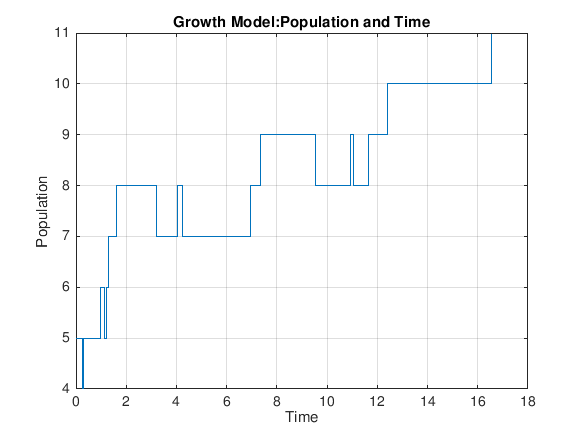

stairs(Tm,Pm)
title('Growth Model:Population and Time')
xlabel('Time')
ylabel('Population')
grid on

#### Estimating time until extinction(independent of previous calculations and graph)

%Resetting Parameters to initial value
disp("Now computing time unto extinction.")

Now computing time unto extinction.


n=ni;
bn=((8.12*n)+2.43)/60;
dn=(9.04*n)/60;
para=bn+dn;
time_total=0;
holdtime=0;
while n>0 %loop for extinction
    u=rand; %Random variable for hold time
    v=rand; %Random variable to simulate birth or death
    holdtime=(-1/para)*log(u);
    time_total=time_total+holdtime;
    fprintf("Time established in simulation is %f min",time_total)
    Pinc=bn/(bn+dn);
    Pdec=dn/(bn+dn);
    if v<Pinc
        n=n+1;%updating n
    else
        n=n-1;%updating n
    end
    fprintf("Current Population is %i inhabitant(s)",n)
    %Now updating changed birth/death rates
    bn=((8.12*n)+2.43)/60;
    dn=(9.04*n)/60;
    if n==0
        fprintf("Time until extinction is %f min",time_total)
    end
end

Time established in simulation is 0.179785 min

Current Population is 4 inhabitant(s)

Time established in simulation is 0.214217 min

Current Population is 3 inhabitant(s)

Time established in simulation is 0.466992 min

Current Population is 4 inhabitant(s)

Time established in simulation is 0.498528 min

Current Population is 3 inhabitant(s)

Time established in simulation is 0.525312 min

Current Population is 4 inhabitant(s)

Time established in simulation is 0.727659 min

Current Population is 5 inhabitant(s)

Time established in simulation is 0.808178 min

Current Population is 4 inhabitant(s)

Time established in simulation is 2.464549 min

Current Population is 3 inhabitant(s)

Time established in simulation is 2.572775 min

Current Population is 2 inhabitant(s)

Time established in simulation is 2.856523 min

Current Population is 3 inhabitant(s)

Time established in simulation is 3.475184 min

Current Population is 4 inhabitant(s)

Time established in simulation is 3.924515 min

Current Population is 3 inhabitant(s)

Time established in simulation is 4.205132 min

Current Population is 2 inhabitant(s)

Time established in simulation is 6.668881 min

Current Population is 3 inhabitant(s)

Time established in simulation is 7.200189 min

Current Population is 2 inhabitant(s)

Time established in simulation is 7.574717 min

Current Population is 3 inhabitant(s)

Time established in simulation is 8.390629 min

Current Population is 2 inhabitant(s)

Time established in simulation is 9.633700 min

Current Population is 1 inhabitant(s)

Time established in simulation is 10.589289 min

Current Population is 2 inhabitant(s)

Time established in simulation is 10.759645 min

Current Population is 1 inhabitant(s)

Time established in simulation is 11.258241 min

Current Population is 2 inhabitant(s)

Time established in simulation is 12.258386 min

Current Population is 3 inhabitant(s)

Time established in simulation is 12.505492 min

Current Population is 4 inhabitant(s)

Time established in simulation is 12.864929 min

Current Population is 5 inhabitant(s)

Time established in simulation is 12.901317 min

Current Population is 6 inhabitant(s)

Time established in simulation is 13.119379 min

Current Population is 7 inhabitant(s)

Time established in simulation is 13.489029 min

Current Population is 8 inhabitant(s)

Time established in simulation is 13.675326 min

Current Population is 7 inhabitant(s)

Time established in simulation is 14.024925 min

Current Population is 8 inhabitant(s)

Time established in simulation is 14.105981 min

Current Population is 7 inhabitant(s)

Time established in simulation is 14.135506 min

Current Population is 6 inhabitant(s)

Time established in simulation is 15.648650 min

Current Population is 5 inhabitant(s)

Time established in simulation is 15.683999 min

Current Population is 4 inhabitant(s)

Time established in simulation is 15.782023 min

Current Population is 3 inhabitant(s)

Time established in simulation is 15.920013 min

Current Population is 2 inhabitant(s)

Time established in simulation is 17.088976 min

Current Population is 1 inhabitant(s)

Time established in simulation is 17.134970 min

Current Population is 0 inhabitant(s)

Time until extinction is 17.134970 min